# 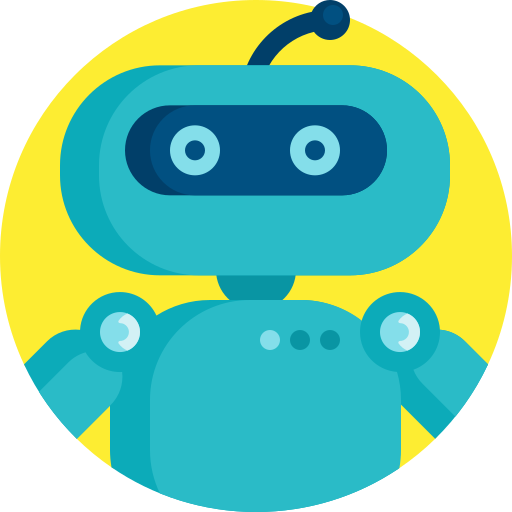

# **MEC4127F: Introduction to Robotics**

# Project — Part 2

## Project brief

You are tasked with designing an attitude control scheme based on the theory covered in **Chapter 10**. The control scheme must use the thrust vectoring approach, with the desired thrust vector in $\{W\}$, ${^W\hat{\bf z}_D}$, provided to you in the Simulink file. The quadcopter must be able to adjust the direction of ${^W\hat{\bf z}_B}$ such that ${^W\hat{\bf z}_B}\rightarrow {^W\hat{\bf z}_D}$ within 2 seconds with a $2\%$ settling tolerance. Additionally, the feedback control scheme must be resistant to external disturbances acting on the quadcopter. The maximum allowed overshoot when adjusting the thrust vector is $15\%$. The following information is also provided to you:

#### Mass moment of inertia matrix:

${\bf J} = \text{diag}\{J_{xx},J_{yy},J_{zz}\}$, where

- $J_{xx}\approx 2\times 10^{-3}$ kgm$^2$,

- $J_{yy}\approx 2.3\times 10^{-3}$ kgm$^2$,

- $J_{zz}\approx 4.5\times 10^{-3}$ kgm$^2$.

#### Motor speed actuation:

It is given that the motors have a delay period of $t_d=0.005$ seconds. 

Note that you do not have to implement the motor speed mappings. You can assume that the mapping is performed within the provided dynamics block. 

#### Simulink file

You are provided with the accompanying simulink file, **Project_Part2.slx**, where you will construct and test your attitude control scheme. The control scheme must be implemented solely using Simulink blocks — user-defined MATLAB functions are not permitted. The dynamics block, reference signal, and other minor additions have been provided.

You will require the following toolboxes for the simulation:

- Control Systems Toolbox,

- Aerospace Toolbox.

Toolboxes can be installed retroactively by going to *APPS* in MATLAB, followed by *Get More Apps*, clear the filter and then search for the name of the toolbox. Lastly, click install, which may prompt a restart from MATLAB, depending on the toolbox.

#### Generating data

The quadcopter is initialised such that ${^W{\bf q}_B}=[1~~0~~0~~0]^T$ at $t=0$ seconds. You can also assume that the position of the quadcopter is always fixed in space. 

When the simulation is run, data is outputted to the MATLAB workspace using the `out` time-series variable (see below). Code blocks are provided below to assist with the design and documenting of your project "report". 

#### Questions to answer

The questions can be found in the Amathuba **Project — Part 2** quiz. 

## Frequency domain design

The code block below is copied from the **Chapter 10 **notes and can be used to design the requisite controllers. You may consider copy and pasting this block when designing your different controllers.

clear
s = tf('s');

% P = ?;
% G = ?; 
L = P*G;

% Ts = ?;
% OS = ?;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
nichols(L,{0.01,500}),plot(-180,0,'ro',MarkerFaceColor='r'),title('Roll controller design — SMTJOH999')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$',Interpreter="latex")
xlim([-360,0]),ylim([-20 40])

## Logged data

The **Project_Part2.slx** simulation must be run before this information is available in the `MATLAB` workspace. Note that after closing and reopening `MATLAB`, the workspace is cleared.

zb2w = out.zb2w.Data;
zdes = out.zdes.Data;
wb = out.wb.Data;
time = out.zb2w.Time;

### Comparison between ${^W\hat{\bf z}_B}$ and ${^W\hat{\bf z}_D}$

This code block generates a comparison between ${^W\hat{\bf z}_B}$ and ${^W\hat{\bf z}_D}$. 

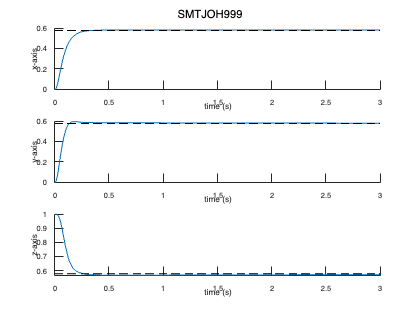

figure(1),clf,sgtitle('SMTJOH999')
subplot(3,1,1),hold on
plot(time,zb2w(:,1)),line([0 time(end)],[zdes(1) zdes(1)],'LineStyle','--','color','k')
xlabel('time (s)'),ylabel('x-axis')
subplot(3,1,2),hold on
plot(time,zb2w(:,2)),line([0 time(end)],[zdes(2) zdes(2)],'LineStyle','--','color','k')
xlabel('time (s)'),ylabel('y-axis')
subplot(3,1,3),hold on
plot(time,zb2w(:,3)),line([0 time(end)],[zdes(3) zdes(3)],'LineStyle','--','color','k')
xlabel('time (s)'),ylabel('z-axis')

### Angular velocity about $\hat{\bf z}_B$

This code block generates a visualisation of the angular velocity about $\hat{\bf z}_B$.

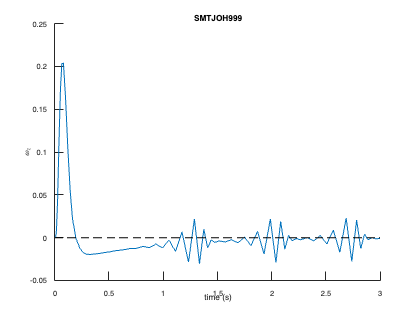

figure(1),clf,hold on,title('SMTJOH999')
plot(time,wb(:,3))
line([0 time(end)],[0 0],'LineStyle','--','color','k')
xlabel('time (s)'),ylabel('$\omega_z$',Interpreter='latex')